clear

addpath("matlab_functions\")

#### Add defect to plate

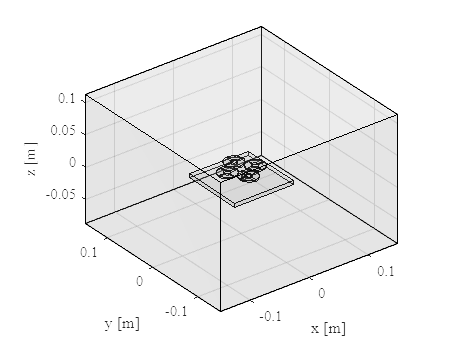

[Plate, Coil, Sensor, Model] = myModel;
freqs = [900 225 100 55]; % (Hz)
mesh_size = 2; % 1:finest 9:coarsest

global defects
defects = {};

% ComsolModel('AddRectangularDefect', Model, 5e-3, 0, 4e-3, 4e-3, 0, -3e-3)
ComsolModel('AddCircularDefect',    Model, 5e-3, 0, 4e-3,       0, -3e-3)

figure
ComsolModel('PlotGeometry', Model)

#### Compute fields

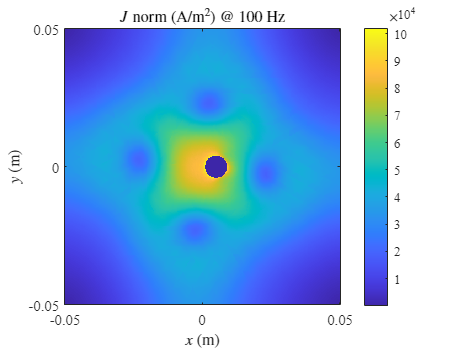

mat2 = Model.component('mod1').material('mat2');

B_data = zeros(length(freqs), size(Sensor.positions,2));

for i = 1:length(freqs)
    mat2.active(true);
    ComsolModel('SolveCoil', Model, Coil, freqs(i), mesh_size);

    [Bx,By,Bz] = ComsolModel('InterpField', Model, {'Bx' 'By' 'Bz'}, ...
        Sensor.positions(1,:), Sensor.positions(2,:), Sensor.positions(3,:));
    B_data(i,:) = dot([Bx;By;Bz], Sensor.axes);
    

    [x,y,z] = ndgrid( ...
        linspace(-Plate.length/2, Plate.length/2, 500), ...
        linspace(-Plate.length/2, Plate.length/2, 500), ...
        -2e-3 );
    normJ = ComsolModel('InterpField', Model, 'normJ', x,y,z);
    
    figure
    imagesc([min(x) max(x)],[min(y) max(y)], ...
            normJ.')
    colorbar
    axis square xy
    xlabel('$x$ (m)', 'Interpreter','latex')
    ylabel('$y$ (m)', 'Interpreter','latex')
    title(sprintf('$J$ norm (A/m$^2$) @ %d Hz',freqs(i)), 'Interpreter','latex')


    mat2.active(false);
    ComsolModel('SolveCoil', Model, Coil, freqs(i), mesh_size);

    [Bx,By,Bz] = ComsolModel('InterpField', Model, {'Bx' 'By' 'Bz'}, ...
        Sensor.positions(1,:), Sensor.positions(2,:), Sensor.positions(3,:));
    B_data(i,:) = B_data(i,:) - dot([Bx;By;Bz], Sensor.axes);
end


clear i x y z r J B mesh_size

#### Export sensor data

fname = sprintf('data/B_%s.txt', datetime('now','Format','MMdd-HHmm'));

fid = fopen(fname, 'w');

for i = 1:length(defects)
    fprintf(fid, '%% defect %s\n', jsonencode(defects{i}));
end
for i = 1:length(freqs)
    fprintf(fid, '%% frequency %g Hz\n', freqs(i));
    fprintf(fid, '%s\n', num2str(B_data(i,:)));
end

fclose(fid);

clear fname fid i